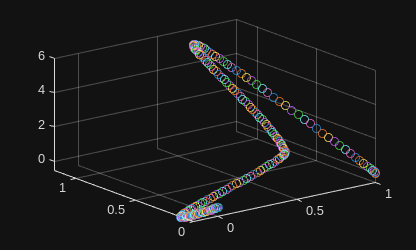

a_conditions = [
    0 0 0;
    0 0 0;
    0 0 0;
];

b_conditions = [
    0.5 0.1 2;
    0.3 0.7 1.5;
    0 0 0;
];

c_conditions = [
    1 0 0;
    0 0 0;
    0 0 0;
];

[Xab,Yab,Zab,delta_tab] = quinticPolynomialTrajectory(a_conditions,b_conditions,1.0);
[Xbc,Ybc,Zbc,delta_tbc] = quinticPolynomialTrajectory(b_conditions,c_conditions,2.0);

combinedX = [Xab; Xbc];
combinedY = [Yab; Ybc];
combinedZ = [Zab; Zbc];

scatter3(combinedX,combinedY,combinedZ)